images\starfish.jpg


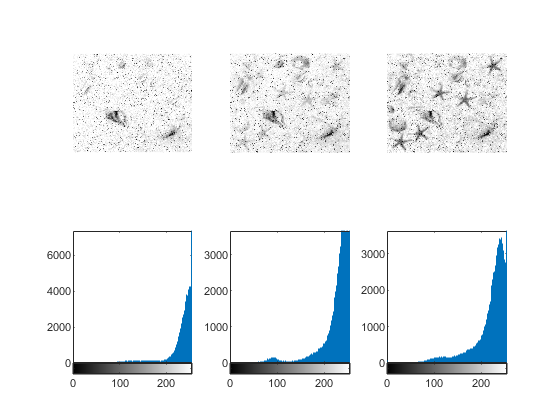

images\starfish_map0.jpg


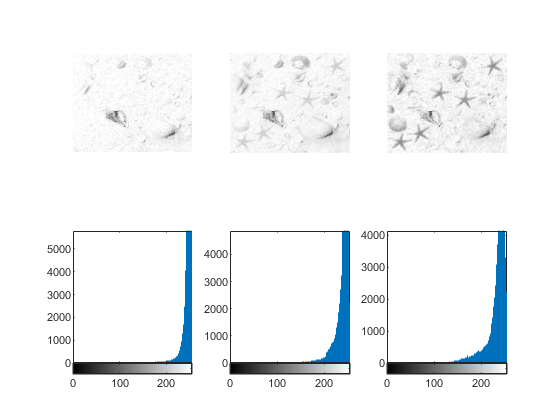

images\starfish_map1.jpg


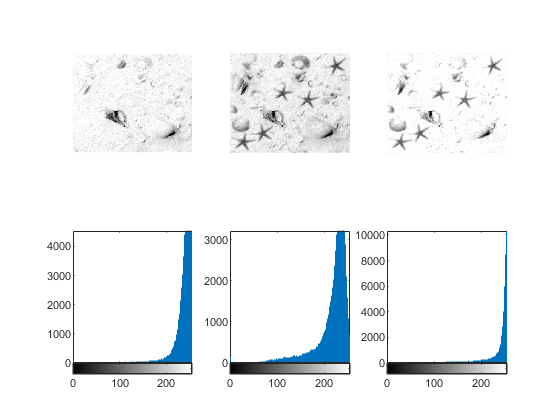

images\starfish_map2.jpg


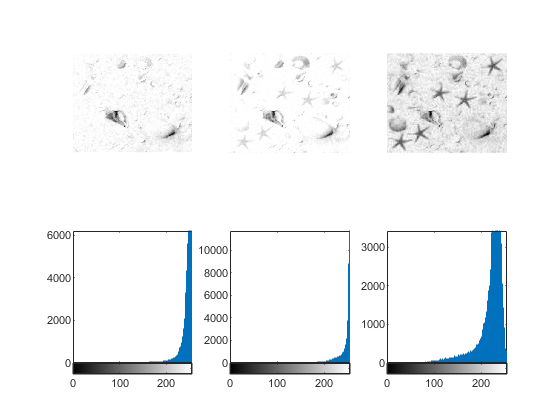

images\starfish_map3.jpg


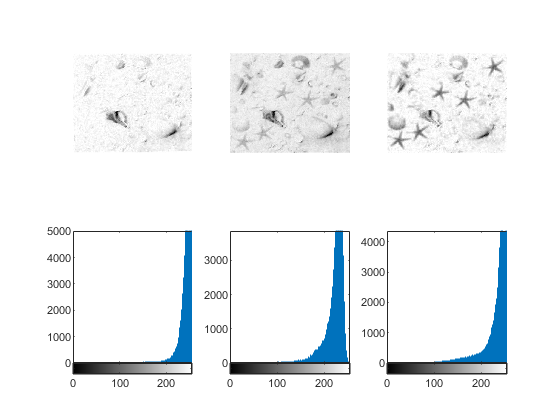

images\starfish_noise1.jpg


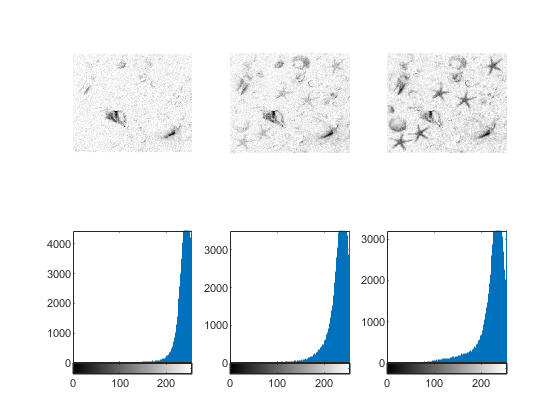

images\starfish_noise10.jpg


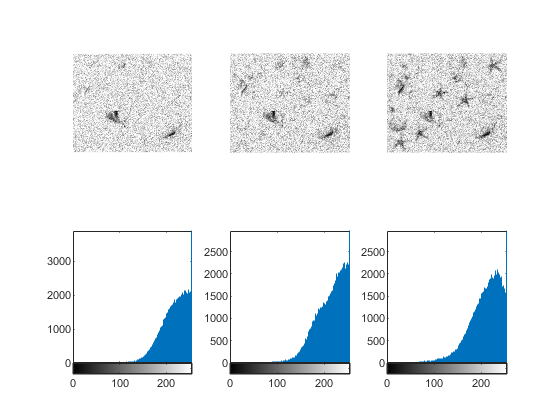

images\starfish_noise2.jpg


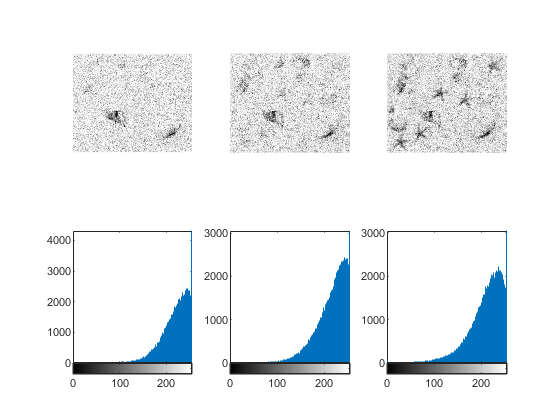

images\starfish_noise3.jpg


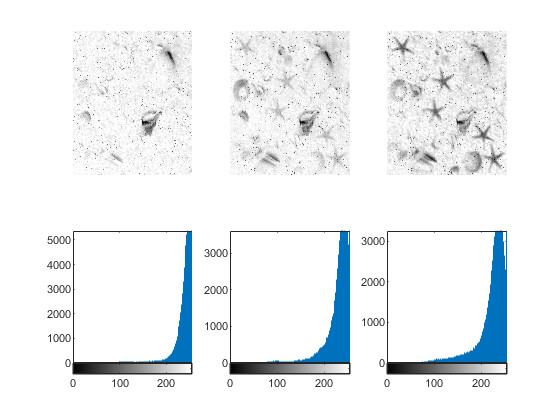

images\starfish_noise4.jpg


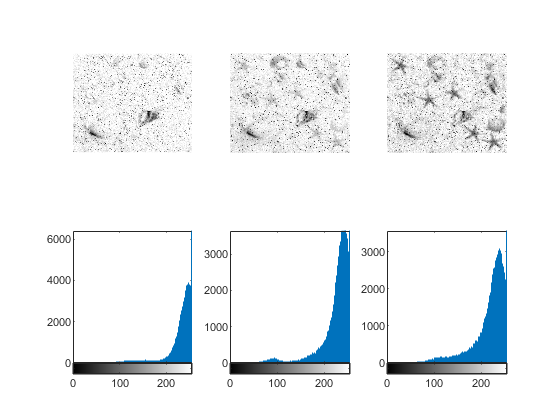

images\starfish_noise5.jpg


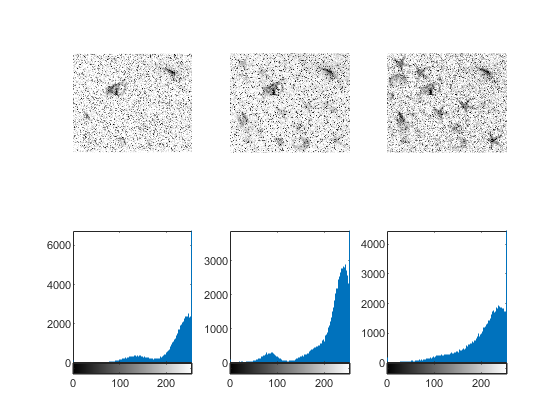

images\starfish_noise6.jpg


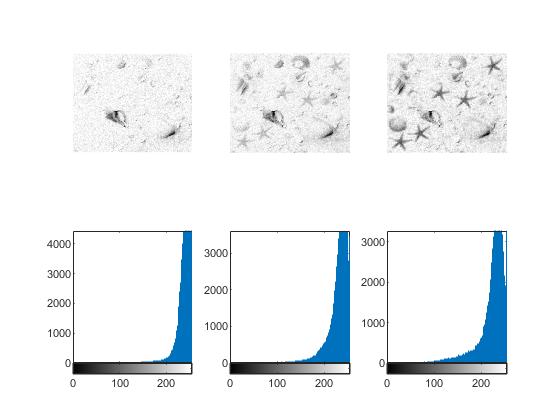

images\starfish_noise7.jpg


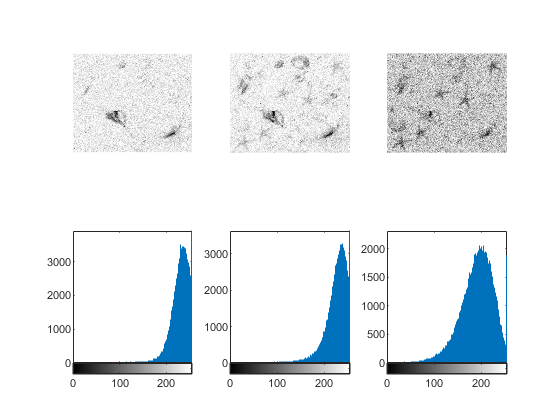

images\starfish_noise8.jpg


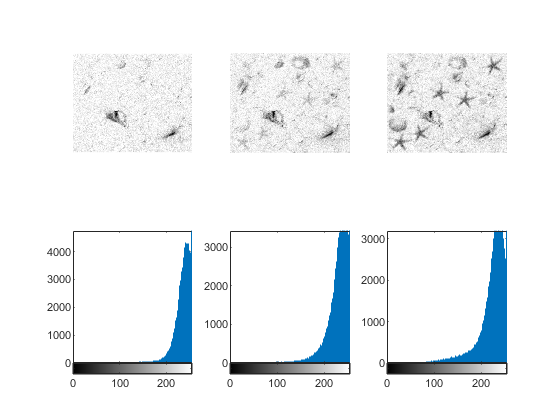

images\starfish_noise9.jpg


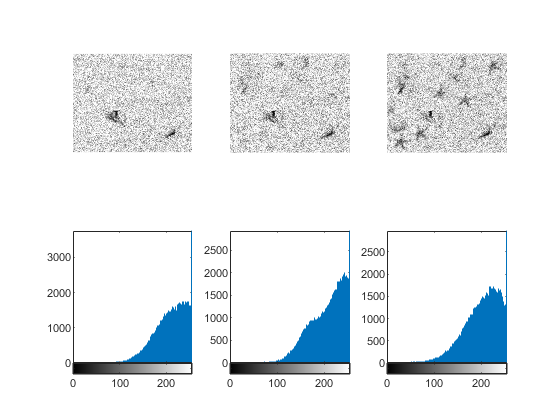

DisplayAllImages();

function filepaths = GetFilesInSubDir(subDir)
    files = dir(subDir);
    files = files(~ismember({files.name}, {'.', '..'})); % Remove navigation elements from struct.
    files = files(contains({files.name}, {'starfish.', 'starfish_map', 'starfish_noise'})); % Get basic images only.
    filepaths = subDir + "\" + {files.name};
end

function DisplayAllImages()
    files = GetFilesInSubDir("images");
    
    for i = 1:numel(files)
        filepath = files(i);
        
        disp(filepath)
        
        im = imread(filepath);
        imG = rgb2gray(im);
        [c1,c2,c3] = imsplit(im);
        
%         figure
%         imshow(im)
        figure
        subplot(2,3,1)
        imshow(c1)
        subplot(2,3,2)
        imshow(c2)
        subplot(2,3,3)
        imshow(c3)
        subplot(2,3,4)
        imhist(c1)
        subplot(2,3,5)
        imhist(c2)
        subplot(2,3,6)
        imhist(c3)
    end
end